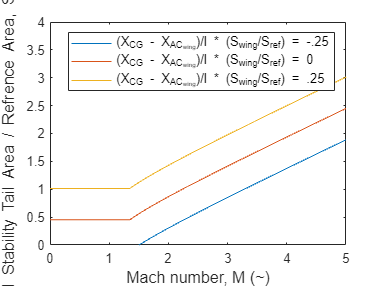

clear; close; clc;
% fleeman geometric definitions
l = convlength(144,"in","m");
d = convlength(8,"in","m");
A_wing = 2.82;
S_ref = convlength(convlength(.349,"ft","m"),"ft","m"); % rerence area
S_wing = convlength(convlength(2.55,"ft","m"),"ft","m"); % planform area
c_mac_wing = convlength(13.3,"in","m"); % mean aerodynamic cord
x_CG = l/2;
x_AC_body = d;
x_AC_T = l - d;
a = [-.25, 0, .25];
%a = 0;

%english units
% l = 144/12; % ft
% d = 8/12; % ft
% A_wing = 2.82;
% S_ref = .349; % rerence area ft^2
% S_wing = 2.55; % planform area ft^2
% c_mac_wing = 13.3/12; % mean aerodynamic cord ft
% x_CG = l/2;
% x_AC_body = d;
% x_AC_T = l - d;
% a = [-.25, 0, .25];

nPoints = 1000;
S_T = zeros([length(a),nPoints]);

for j = 1:length(a)

    x_AC_W = x_CG - a(j) * l * S_ref / S_wing; % for fleeman plots (looks way better if use d rather than l)
    C_N_alpha_body = 2; % per radian
    
    
    % prepare for component buildup
    x_AC_components = [x_AC_body, x_AC_W];
    %convlength(x_AC_W, "m", "in")
    S_components = [S_ref, S_wing];
    
    %fleeman definitions
    % X_CG_burnout = convlength(76.2, "in", "m");
    % X_mac = convlength(67.0, "in", "m");
    % X_
    
    % initialize loop variables
    %nPoints = 1000;
    M = linspace(0, 5, nPoints);
    %S_T = zeros(0,nPoints);
    
    
    
    for i = 1:nPoints
        %fleeman definitions
        C_N_alpha_wing = normalForce_withRespectTo_alpha_planar_surface(M(i), S_ref, S_wing, A_wing);

        % solve for drag explicity without fleeman formulae
%         if M(i) > ((1 + (8 / (pi*A_wing))^2)^.5)
%             C_N_alpha_wing = 4/(M(i)^2-1)^.5 * (S_wing/S_ref);
%         else
%             C_N_alpha_wing = pi*A_wing/2 * (S_wing/S_ref);
%         end

%         if M(i) > ((1 + (8 / (pi*A_wing))^2)^.5)
%             C_N_alpha_wing = 4/(M(i)^2-1)^.5;
%         else
%             C_N_alpha_wing = pi*A_wing/2;
%         end

        C_N_alpha_tail(j,i) = C_N_alpha_wing;

        % prepare for component buildup
        C_N_alpha_components = [C_N_alpha_body, C_N_alpha_wing];
        
        S_T(j,i) = tail_area_sizing(x_CG, x_AC_T, x_AC_components, S_ref, S_components, C_N_alpha_tail(j,i), C_N_alpha_components);
        % this should be the same as the above line of code. it is not
        % quite the same. the below one is from fleeman the above one i
        % derived myself. neither work
        %S_T(j,i) = - S_ref * (C_N_alpha_body * (x_CG - x_AC_body) + C_N_alpha_wing * (S_wing / S_ref) * (x_CG - x_AC_W) ) / (C_N_alpha_tail(j,i) * (x_CG - x_AC_T));
        %S_T(j,i) = - S_ref * (C_N_alpha_body * (x_CG - x_AC_body) + C_N_alpha_wing * a(j) ) / (C_N_alpha_tail(j,i) * (x_CG - x_AC_T));
    end

end

plot(M, S_T/S_ref); ylim([0,4]); xlabel("Mach number, M (~)", "FontSize", 12, Interpreter="tex"); ylabel("Neutral Stability Tail Area / Refrence Area, S_T/S_{ref} (~)", "FontSize", 12, Interpreter="tex"); legend(["(X_{CG} - X_{AC_{wing}})/l * (S_{wing}/S_{ref}) = -.25", "(X_{CG} - X_{AC_{wing}})/l * (S_{wing}/S_{ref}) = 0", "(X_{CG} - X_{AC_{wing}})/l * (S_{wing}/S_{ref}) = .25"], FontSize=10)

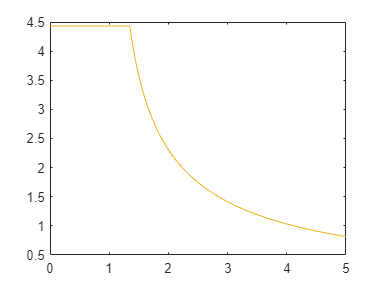

plot(M, C_N_alpha_tail);